# Klasyfikacja obrazów przy użyciu bag-of-visual-words

## Parametry działania

% Liczba obrazów treningowych na klasę
cnt_train = 40;

% Liczba obrazów testowych na klasę
cnt_test = 10;

% Wybrane klasy obiektów
img_classes = {'deli', 'greenhouse', 'bathroom'};

% Liczba cech wybierana na każdym obrazie
feats_det = 100;

% Metoda wyboru cech (true - jednorodnie w całym obrazie, false - najsilniejsze)
feats_uniform = true;

% Wielkość słownika
words_cnt = 30;

## Detekcja cech

### Ładowanie pełnego zbioru danych z automatycznym podziałem na klasy

Zbiór danych pochodzi z publikacji: A. Quattoni, and A.Torralba. [*Recognizing Indoor Scenes*](http://people.csail.mit.edu/torralba/publications/indoor.pdf). IEEE Conference on Computer Vision and Pattern Recognition (CVPR), 2009.

Pełny zbiór dostępny jest na stronie autorów: [http://web.mit.edu/torralba/www/indoor.html](http://web.mit.edu/torralba/www/indoor.html)

imds_full = imageDatastore("indoor/indoorCVPR_09/Images/", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(imds_full)

ans = 67×2 table
        Label         Count
    ______________    _____

    airport_inside     608 
    artstudio          140 
    auditorium         176 
    bakery             405 
    bar                604 
    bathroom           197 
    bedroom            662 
    bookstore          379 
    bowling            213 
    buffet             108 
    casino             515 
    children_room      112 
    church_inside      180 
    classroom          113 
    cloister           120 
    closet             132 


### Wybór przykładowych klas i podział na zbiór treningowy i testowy

[imds, imtest] = splitEachLabel(imds_full, cnt_train, cnt_test, 'Include', img_classes);
countEachLabel(imds)

ans = 3×2 table
      Label       Count
    __________    _____

    bathroom       40  
    deli           40  
    greenhouse     40  


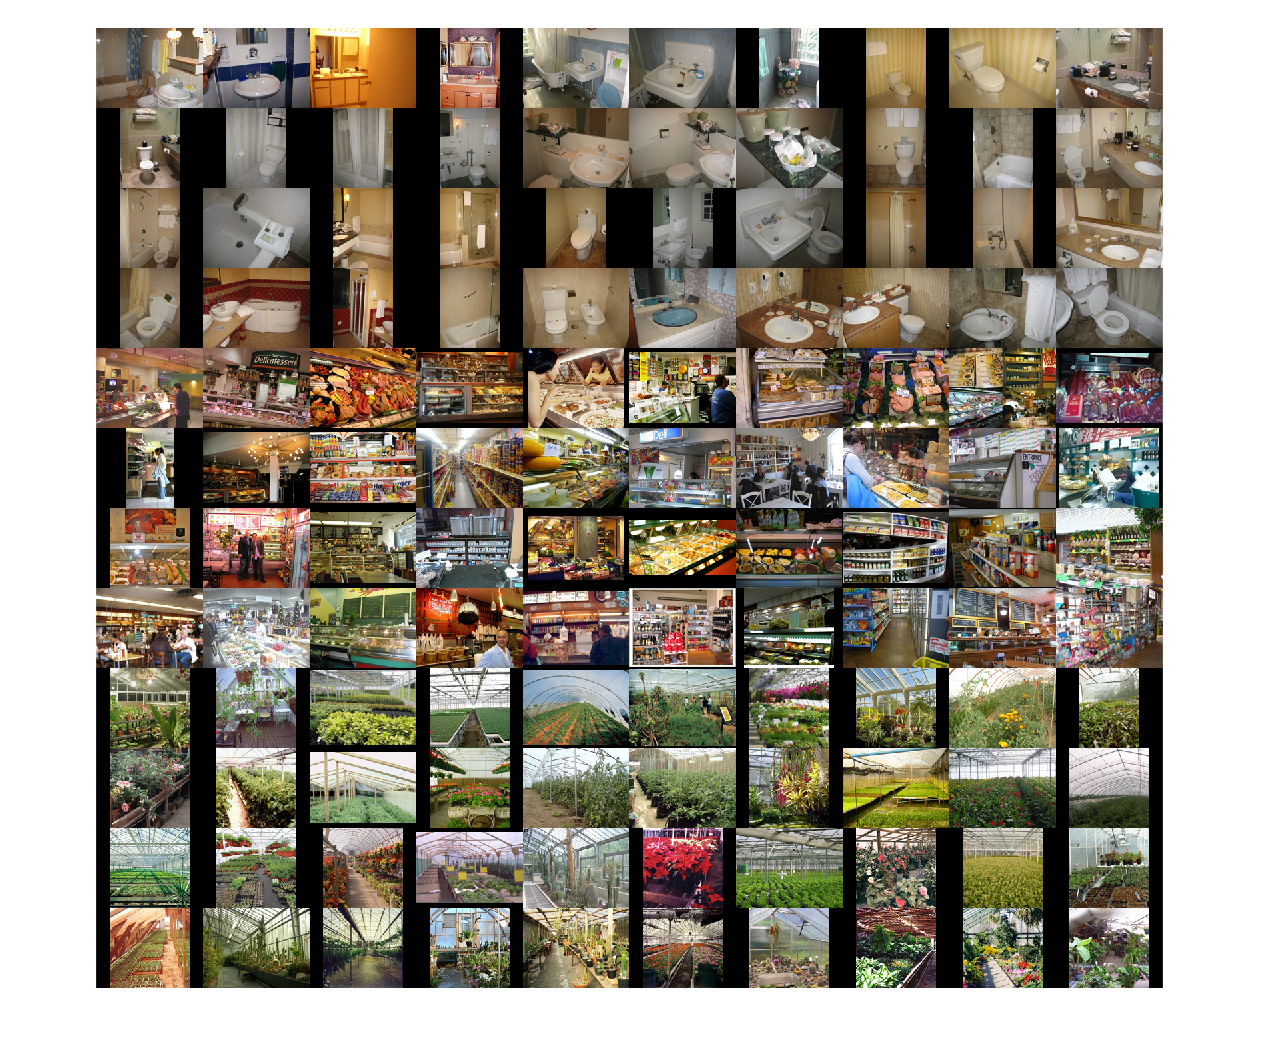

montage(imds, 'Size', [NaN, 10]);

### Wyświetlenie wybranego obrazu wraz z wizualizacją najsilniejszych cech

#### Dobór odpowiedniej metody filtrowania cech (parametr feats_uniform)

W przypadku wyboru do dalszego przetwarzania cech jedynie na podstawie ich siły istnieje ryzyko, że jeden fragment obrazu zdominuje całkowicie zbiór cech dla danego zdjęcia.

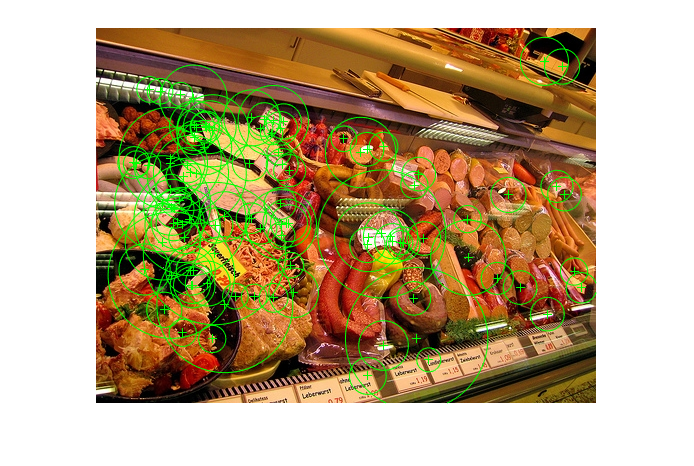

I = readImage(imds.Files{43});
imshow(I); hold on;
pts = getFeaturePoints(I, feats_det, false);
plot(pts);

Zamiast wybierać cechy jedynie na podstawie ich siły można zastosować wybór przestrzenny, w którym punkty będą próbkowane możliwie równomiernie z całego obszaru obrazu.

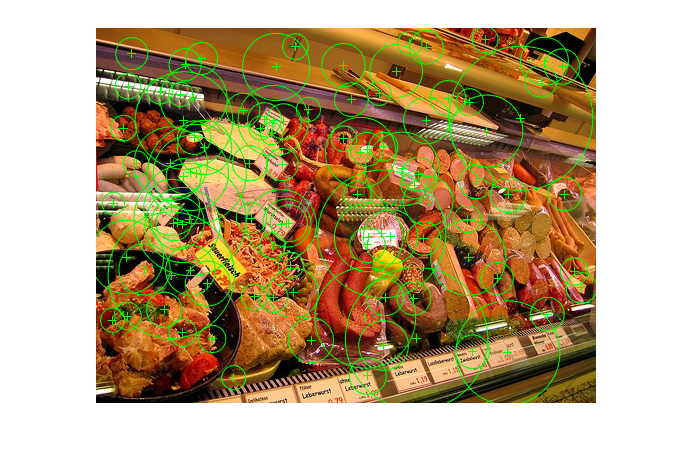

figure;
imshow(I); hold on;
pts = getFeaturePoints(I, feats_det, true);
plot(pts);

W ramach wizualizacji można wyświetlić otoczenie punktu kluczowego z uwzględnieniem skali, dla której został on wyznaczony.

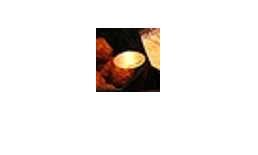

figure;
imshow(getPatch(I, pts.Location(1, :), pts.Scale(1), 12));

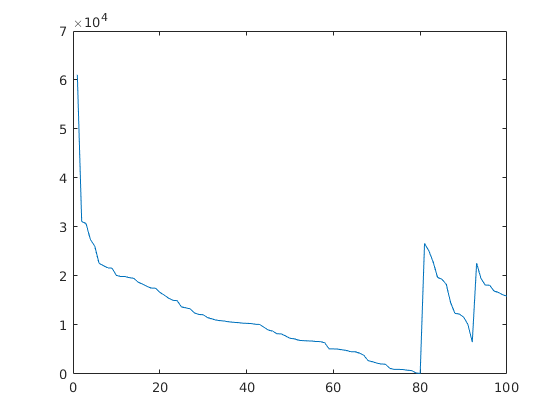

figure;
plot(pts.Metric);

### Wyznaczenie punktów charakterystycznych we wszystkich obrazach zbioru treningowego

files_cnt = length(imds.Files);
all_points = cell(files_cnt, 1);
total_features = 0;

for i=1:files_cnt
    I = readImage(imds.Files{i});
    all_points{i} = getFeaturePoints(I, feats_det, feats_uniform);
    total_features = total_features + length(all_points{i});
end

### Przygotowanie listy przechowującej indeksy plików i punktów charakterystycznych

file_ids = zeros(total_features, 2);
curr_idx = 1;
for i=1:files_cnt
    file_ids(curr_idx:curr_idx+length(all_points{i})-1, 1) = i;
    file_ids(curr_idx:curr_idx+length(all_points{i})-1, 2) = 1:length(all_points{i});
    curr_idx = curr_idx + length(all_points{i});
end

### Obliczenie deskryptorów punktów charakterystycznych

all_features = zeros(total_features, 64, 'single');
curr_idx = 1;
for i=1:files_cnt
    I = readImage(imds.Files{i});
    curr_features = extractFeatures(rgb2gray(I), all_points{i});
    all_features(curr_idx:curr_idx+length(all_points{i})-1, :) = curr_features;
    curr_idx = curr_idx + length(all_points{i});
end

## Tworzenie słownika

### Klasteryzacja punktów 

Deskryptorów punktów charakterystycznych wyznaczonych we wszystkich obrazach treningowych są umieszczone we wspólnej tablicy. Algorytm k-średnich stara się dopasować wybraną liczbę wektorów wzorcowych (parametr words_cnt) do całego zbioru danych. 

[idx, words, sumd, D] = kmeans(all_features, words_cnt, "MaxIter", 500);

### Wizualizacja wyliczonych słów

Dla każdego wyznaczonego wektora wzorcowego (słowa) wyszukiwane jest 10 najbliższych mu cech w zbiorze treningowym. Te cechy mogą stanowić pewną podpowiedź na temat tego, co reprezentuje dane słowo. W większości przypadków słowa reprezentują pewne łatwo rozpoznawalne struktury geometryczne, jednak nie jest to regułą. Należy pamiętać, że deskryptor SURF jest wyznaczany z obrazu w odcieniach szarości, więc kolor ie wpływa na jego wartość. Na obrazie stworzonym poniżej każdy wiersz to jedno słowo.

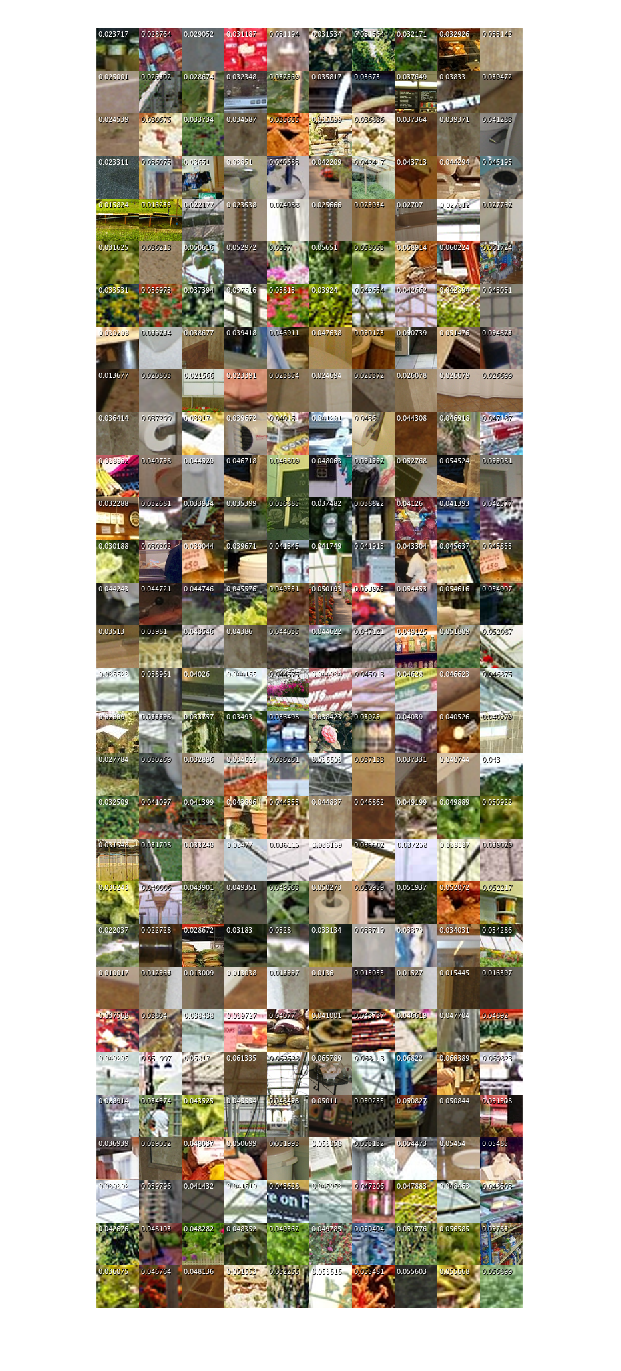

cnt = 10;
word_vis = zeros(64*words_cnt, 64*cnt, 3, 'uint8');
for ft = 1:words_cnt
    [mind, mini] = mink(D(:, ft), cnt);
    for i = 1:cnt
        img_id = file_ids(mini(i), 1);
        pt_id = file_ids(mini(i), 2);
        I = readImage(imds.Files{img_id});
        pt = all_points{img_id}.Location(pt_id, :);
        scale = all_points{img_id}.Scale(pt_id);
        scale_factor = 12;
        P = getPatch(I, pt, scale, scale_factor);
        P = insertText(P, [2, 2], mind(i), 'FontSize', 10, 'BoxOpacity', 0);
        P = insertText(P, [1, 1], mind(i), 'FontSize', 10, 'BoxOpacity', 0, 'TextColor', 'white');
        word_vis(((ft-1)*64+1):(ft*64), ((i-1)*64+1):(i*64),:) = P;
    end
end
imshow(word_vis);

imwrite(word_vis, "word_vis.png");

### Wyznaczenie histogramów słów dla każdego obrazu treningowego

Algorytm k-średnich, oprócz wyznaczenia samych słów wzorcowych, przypisuje też wszystkie deskryptory do najbliższych słów. Zliczając przypisania dla każdego ze słów tworzy się histogram będący kompaktową reprezentacją dla każdego obrazu uczącego. Histogram jest normalizowany w taki sposób, aby suma jego elementów wynosiła 1, dzięki czemu uniezależniamy się od liczby cech wykrytych w obrazie.

file_hist = zeros(files_cnt, words_cnt);
for i=1:files_cnt
    file_hist(i,:) = histcounts(idx(file_ids(:,1) == i), (1:words_cnt+1)-0.5, 'Normalization', 'probability');
end

## Porównywanie podobieństwa obrazów

### Analiza podobieństwa w danych treningowych

Jedną z metod wstępnej weryfikacji poprawności stworzenia słownika jest analiza podobieństwa pomiędzy obrazami w zbiorze treningowym. W przypadku idealnym dystans pomiędzy reprezentantami tej samej klas powinien być niski, a pomiędzy klasami jego wartość powinna rosnąć. Po wyznaczeniu wszystkich par odległości pomiędzy wyznaczonymi w poprzednim kroku histogramami dla plików można je wyświetlić w postaci kwadratowej macierzy, gdzie element na przecięciu wiersza *w* i kolumny *k* odpowiada odległości pomiędzy histogramami dla obrazów o odpowiednich indeksach w zbiorze treningowym. Punkty ciemniejsze odpowiadają histogramom podobnym, jaśniejsze różniącym się od siebie.

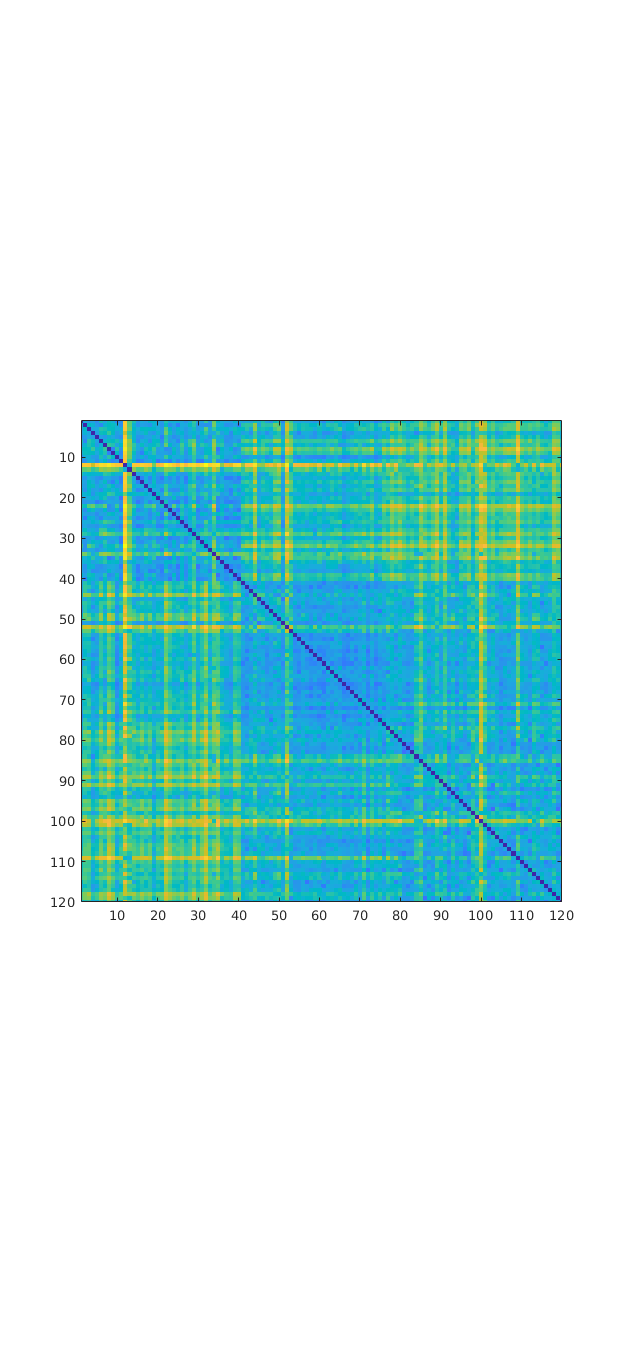

tr_dist = pdist2(file_hist, file_hist);
imagesc(tr_dist);
axis equal;
xlim([1 length(imds.Files)]);
ylim([1 length(imds.Files)]);

Oczekiwanym wzorcem na wykresie powinny być trzy ciemniejsze kwadraty o wielkości 40x40 (tyle, ile obrazów uczących w każdej z klas) otoczone jaśniejszymi punktami. Występowanie w obrazie linii znacząco odcinających się od otoczenia jest wskazówką dotyczącą zbioru treningowego - dany element (obraz) jest znacząco różny od wszystkich innych. Czasami jest to oznaką nieprawidłowego stworzenia zbioru treningowego, częściej po prostu oznacza bardzo trudny przypadek.

### Analiza pojedynczego obrazu

Mając wyznaczony histogram dla wszystkich obrazów treningowych można spróbować znaleźć wśród nich obrazy najbardziej podobne do zadanego obrazu testowego. 

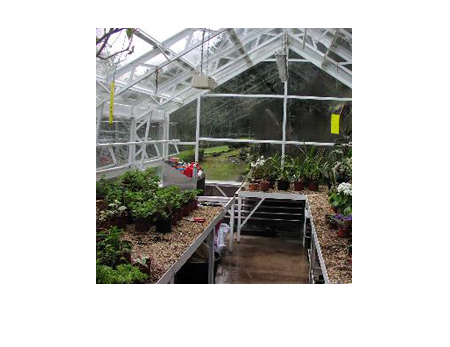

I = readImage(imtest.Files{23});
imshow(I);

### Wyznaczenie cech i wizualizacja histogramu

W pierwszym kroku należy, w podobny sposób jak dla obrazów treningowych, wyznaczyć histogram obrazu testowego. Dodatkowo wyświetlana jest wizualizacja histogramu za pomocą fragmentów obrazu, które zostały dopasowane do danego słowa. Fragmenty te powinny być przynajmniej częściowo podobne do wizualizacji słów wykonanej na początku ćwiczenia.

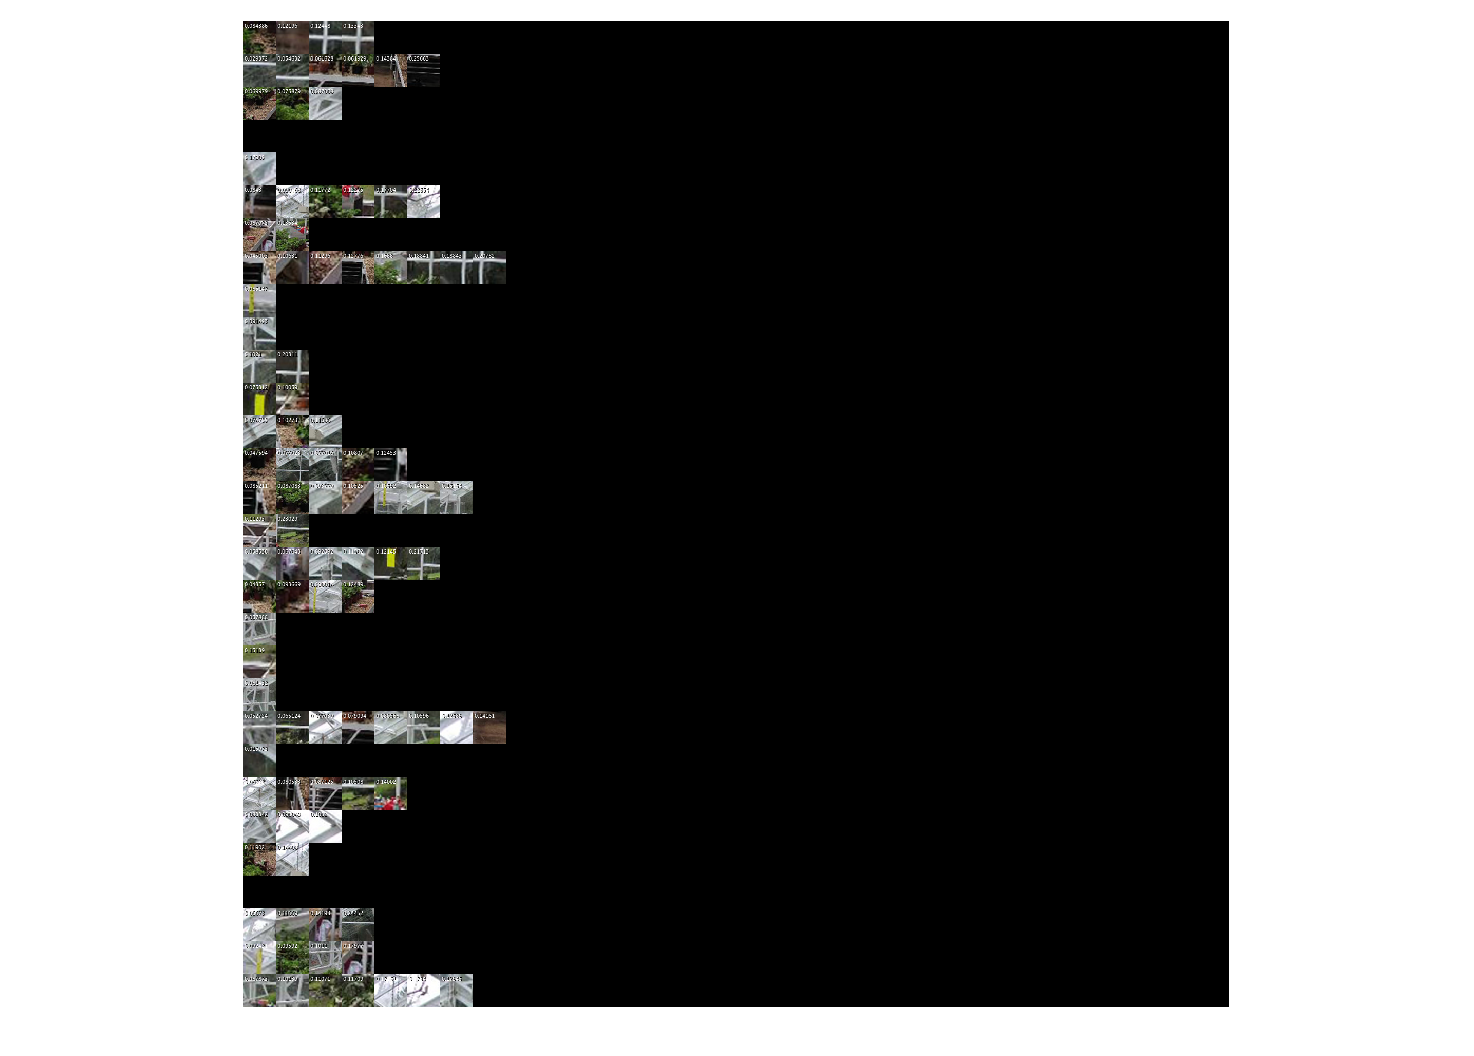

pts = getFeaturePoints(I, feats_det, feats_uniform);
feats = extractFeatures(rgb2gray(I), pts);
[h, P] = visSingleImage(I, pts, feats, words);
imshow(P);

### Obliczenie dystansu do wszystkich zdjęć treningowych i wybranie kilku najbardziej podobnych

Po wyznaczeniu histogramu i obliczeniu jego odległości od wszystkich histogramów treningowych można wybrać pięć najbliższych (najbardziej podobnych) obrazów i je wyświetlić. Teoretycznie powinny wśród nich dominować obrazy z tej samej klasy, co obraz testowy, ale nie zawsze jest to regułą.

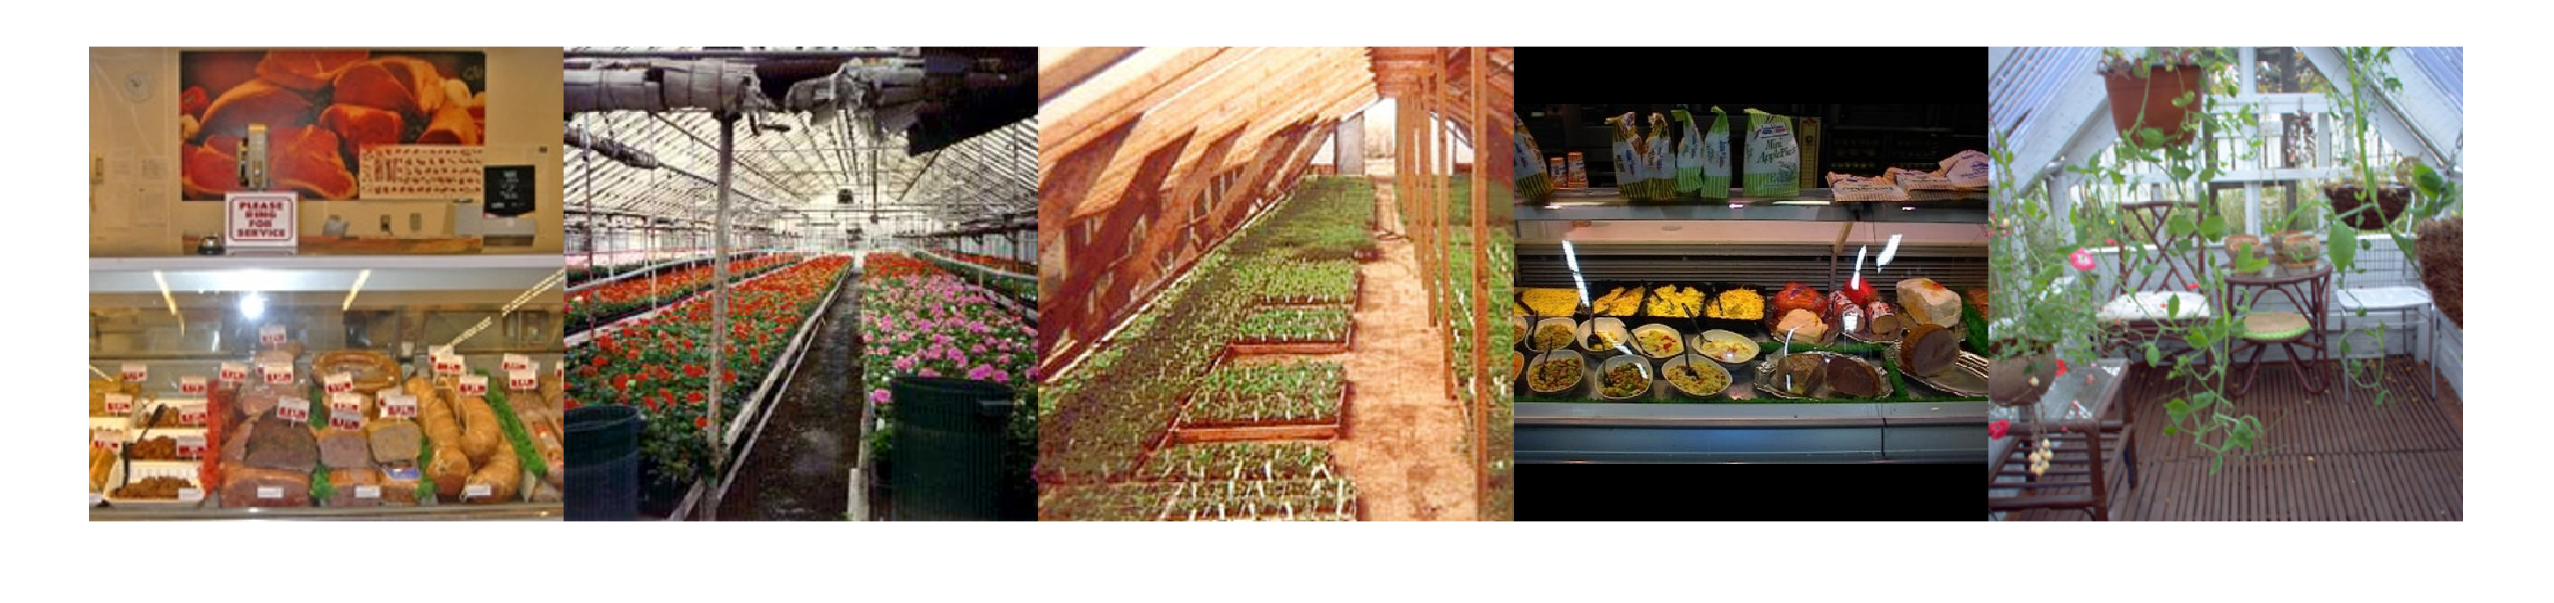

dists = pdist2(h, file_hist);
[~, best_id] = sort(dists);
montage(imds.Files(best_id(1:5)), 'Size', [1, 5]);

## Klasyfikacja danych testowych

Od wyszukiwania obrazów podobnych jest już tylko jeden krok do przeprowadzenia pełnej klasyfikacji zbioru testowego. Dla każdego obrazu testowego wyznaczony jest histogram oraz obliczane są odległości do obrazów treningowych. Wśród najbliższych pięciu obrazów zliczane są ich klasy, a ta, która dominuje, wybierana jest jako odpowiedź klasyfikatora. Zaprezentowany sposób klasyfikacji jest dość prosty i ma swoje wady. Przy klasyfikacji na więcej niż dwie klasy zawsze istnieje ryzyko remisu. Metoda ta nie sprawdza się też (ze względu na konieczność liczenia odległości do wszystkich wzorców treningowych) przy bardzo dużych zbiorach uczących. Dla celów ćwiczenia jest ona jednak wystarczająca.

### Wyznaczenie histogramów słów dla obrazów testowych

test_hist = zeros(length(imtest.Files), words_cnt);
for i=1:length(imtest.Files)
    I = readImage(imtest.Files{i});
    pts = getFeaturePoints(I, feats_det, feats_uniform);
    feats = extractFeatures(rgb2gray(I), pts);
    test_hist(i,:) = wordHist(feats, words);
end

### Wyznaczenie odległość do każdego ze zdjęć treningowych

testD = pdist2(test_hist, file_hist);

### Prosty klasyfikator *k* sąsiadów (k-NN)

k=5;

% k najmniejszych odległości w każdym wierszu
[~, minid] = mink(testD, k, 2);

% kategorie k najbliższych sąsiadów
cats = imds.Labels(minid);

% dominująca kategoria dla każdego zdjęcia testowego
preds = mode(cats, 2);

### Ocena skuteczności

Ostatnim krokiem po dokonaniu klasyfikacji jest jej ocena. Maciecz pomyłek jest jedną z metod określenia zachowania klasyfikatora. Przedstawia ona liczbę próbek, które zostały zaklasyfikowane do poszczególnych klas. Oczekiwanym wynikiem są wartości jedynie na przekątnej (poprawne klasyfikacje) i brak błędów (wartości poza przekątną).

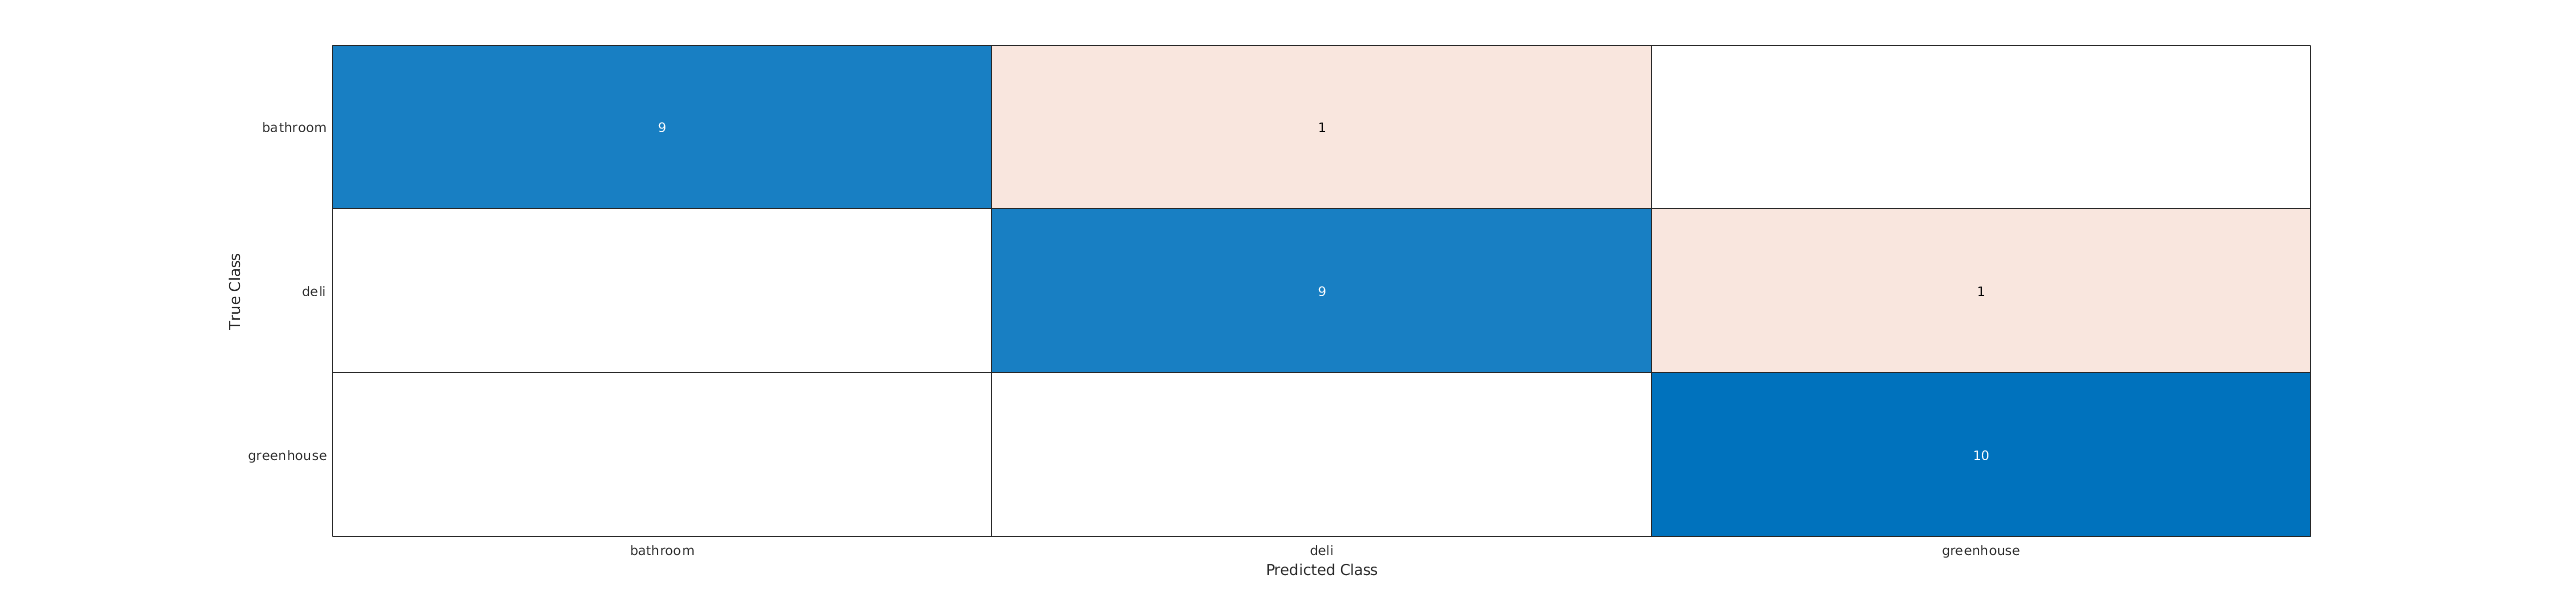

confusionchart(removecats(imtest.Labels), removecats(preds));

## Funkcje pomocnicze

function P = getPatch(I, pt, scale, scale_factor)
    x1 = round(pt(1) - 0.5*scale*scale_factor);
    x2 = round(pt(1) + 0.5*scale*scale_factor);
    y1 = round(pt(2) - 0.5*scale*scale_factor);
    y2 = round(pt(2) + 0.5*scale*scale_factor);
    
    [x1, x2, y1, y2] = clipInside(x1, x2, y1, y2, size(I, 1), size(I, 2));
    
    P = imresize(I(y1:y2, x1:x2, :), [64 64]);
end

function [xr1, xr2, yr1, yr2] = clipInside(x1, x2, y1, y2, rows, cols)
    xr1 = min(max(x1, 1), cols);
    xr2 = min(max(x2, 1), cols);
    yr1 = min(max(y1, 1), rows);
    yr2 = min(max(y2, 1), rows);
end

function pts = getFeaturePoints(I, pts_det, pts_uniform)
    if size(I, 3) > 1
        I2 = rgb2gray(I);
    else
        I2 = I;
    end
    
    pts = detectSURFFeatures(I2, 'MetricThreshold', 100);
    if pts_uniform
        pts = selectUniform(pts, pts_det, size(I));
    else
        pts = pts.selectStrongest(pts_det);
    end
end

function h = wordHist(feats, words)
    words_cnt = size(words, 1);
    dis = pdist2(feats, words, 'squaredeuclidean');
    [~, lbl] = min(dis, [], 2);
    h = histcounts(lbl, (1:words_cnt+1)-0.5, 'Normalization', 'probability');
end

function [h, P] = visSingleImage(I, pts, feats, words)
    words_cnt = size(words, 1);
    dis = pdist2(feats, words, 'squaredeuclidean');
    [dis, lbl] = min(dis, [], 2);
    [~, ids] = sort(dis);
    h = histcounts(lbl, (1:words_cnt+1)-0.5, 'Normalization', 'probability');
    P = zeros(words_cnt*64, 30*64, 3, 'uint8');
    pos = zeros(words_cnt, 1);
    for i=1:size(feats, 1)
        id = ids(i);
        x = pos(lbl(id)) * 64;
        pos(lbl(id)) = min(pos(lbl(id)) + 1, 29);
        y = (lbl(id)-1) * 64;
        pat = getPatch(I, pts.Location(id, :), pts.Scale(id), 12);
        pat = insertText(pat, [2, 2], dis(id), 'FontSize', 10, 'BoxOpacity', 0);
        pat = insertText(pat, [1, 1], dis(id), 'FontSize', 10, 'BoxOpacity', 0, 'TextColor', 'white');
        P(y+1:y+64, x+1:x+64, :) = pat;
    end
end

% Wczytanie obrazu i przeskalowanie jeśli jest zbyt duży
function I = readImage(path)
    I = imread(path);
    if size(I,2) > 640
        I = imresize(I, [NaN 640]);
    end
end